# [Hyperparameter Optimization](https://apmonitor.com/pds/index.php/Main/HyperparameterOptimization)

Hyperparameter options of classification or regression algorithms are settings not learned directly from the training data. The selection of these parameters can be determined by evaluation on a separate set of data that is reserved for optimizing the selection of hyperparameters from specified choices.

Examples of hyperparameters include the learning rate, number of hidden layers, and number of neurons in a neural network, and the regularization term in a linear classifier. The optimal values for these hyperparameters are typically determined through a process called hyperparameter optimization, which involves searching for the best combination of hyperparameter values that result in the best performance of the model on a validation dataset.

## Train, Validation, Test Data

There is a validation data split for hyperparameter optimization to ensure that the model performance is evaluated in an unbiased and accurate way. The training data is used to learn the model parameters, and the validation data is used to evaluate the performance of the model and tune the hyperparameters. The test data is used as a final evaluation of the model performance, after the hyperparameters have been chosen.

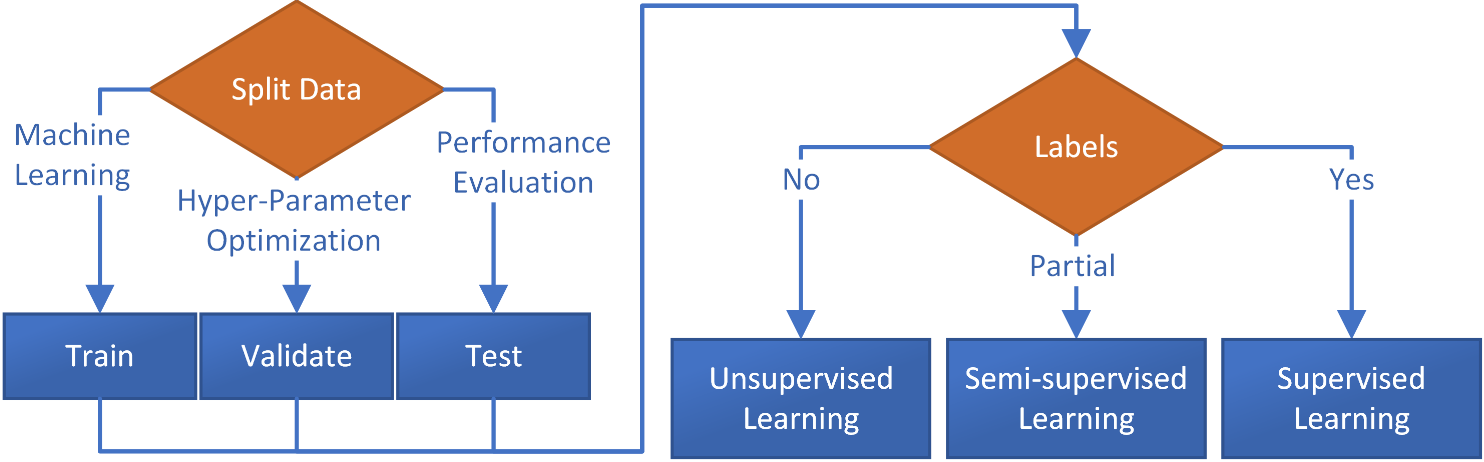

Using the same data for both training and testing the model would result in overfitting, where the model performs well on the training data but poorly on unseen data, because the model has seen the test data during the training process. By keeping the test data separate and only using it as a final evaluation, the model performance on the test data is a true representation of the performance on unseen data. Additionally, using the validation data to tune the hyperparameters and test data to evaluate the performance of the final model helps to prevent the problem of overfitting, by avoiding to use the same data for both tuning and evaluation.

## Hyperparameter Search Methods

There are several [**common methods for hyperparameter optimization**](https://medium.com/criteo-engineering/hyper-parameter-optimization-algorithms-2fe447525903), each with its own strengths and weaknesses:

1️⃣ Grid search: A technique where a set of possible values for each hyperparameter is specified, and the algorithm will train and evaluate a model for each combination of hyperparameter values. Grid search can be computationally expensive, particularly when searching over many hyperparameters or a large range of values for each hyperparameter.

2️⃣ Random search: A technique where a random set of hyperparameter values is sampled from a predefined distribution for each hyperparameter. Random search is less computationally expensive than grid search, but still has a higher chance of finding a good set of hyperparameters than a simple grid search.

3️⃣ Bayesian optimization: A probabilistic model-based approach that uses Bayesian inference to model the function that maps the hyperparameters to the performance of the model. It uses the acquired knowledge to direct the search to the regions where it expects to find the best performance. Bayesian optimization cannot be parallelized and requires continuous hyperparameters (not categorical). It quickly converges to an optimal solution when there are few hyperparameters, but this efficiency degrades when the search dimension increases.

4️⃣ Genetic Algorithm: A evolutionary based algorithm that uses concepts of natural selection and genetics to optimize the parameters.

5️⃣ Gradient-based optimization: A method that uses gradient information to optimize the hyperparameters. This can be done using optimization algorithms such as gradient descent or Adam.

6️⃣ Hyperband: An algorithm that uses the idea of early stopping to decide when to stop training a model, which reduces the number of models that need to be trained and evaluated, making it faster than grid search or random search.

Which method to use depends on the problem, the complexity of the model, the computational resources available, and the desired trade-off between computation time and optimization quality.

## Grid Search

A grid search is a technique for hyperparameter optimization in which a set of possible values for each hyperparameter is specified, and the algorithm will train and evaluate a model for each combination of hyperparameter values. In a grid search, the user defines a grid of hyperparameters to search over, and for each combination of hyperparameter values, the algorithm trains a model using that combination, evaluate it using a metric of choice (such as accuracy or F1 score) and save the results. After training and evaluating all the models, the grid search returns the combination of hyperparameters that achieve the best performance.

For example, in the case of a KNN classifier, a grid search could be used to find the optimal number of neighbors and the optimal weighting method (uniform or distance-based) by specifying a range of values for the hyperparameter (nearest neighbors) and training a model for every combination of those values. The grid search can also use cross-validation, where the data is split into a training and validation set. So for each combination of hyperparameters, the model is trained on the training data and evaluated on the validation data. This prevents overfitting and a better estimate of the generalization performance of the model.

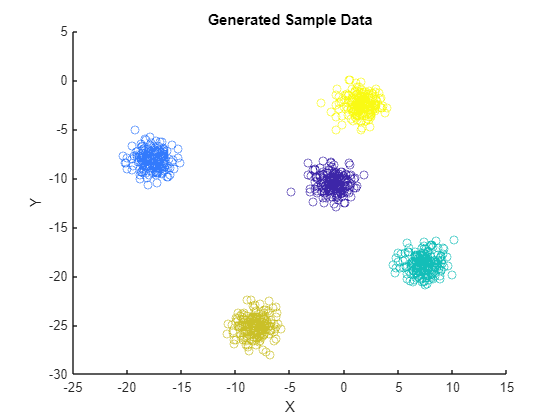

%% Create the data
% rng(10); % Set the random seed

% Parameters for make_blobs
n_samples = 1000;
n_centers = 5;

% Generate sample data
X = [];
y = [];

for i = 1:n_centers
    center = 10 * randn(1, 2); % Random center for each cluster
    covariance = eye(2); % Covariance matrix for each cluster
    samples = mvnrnd(center, covariance, n_samples/n_centers);
    labels = ones(size(samples, 1), 1) * i;
    X = [X; samples];
    y = [y; labels];
end

% Display the generated data
scatter(X(:,1), X(:,2), [], y);
xlabel('X');
ylabel('Y');
title('Generated Sample Data');

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Coding | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |     0.18667 |      0.2847 |     0.18667 |     0.18667 |     onevsall |      0.13266 |       114.46 |
|    2 | Best   |   0.0033333 |      3.8918 |   0.0033333 |    0.015138 |     onevsall |    0.0045065 |    0.0087032 |
|    3 | Best   |           0 |     0.23812 |           0 |  0.00043398 |     onevsone |       44.954 |      0.20964 |
|    4 | Accept |        0.18 |      11.199 |           0 |   0.0078513 |     onevsall |       12.514 |     0.057903 |
|    5 | Accept |           0 |     0.99603 |   

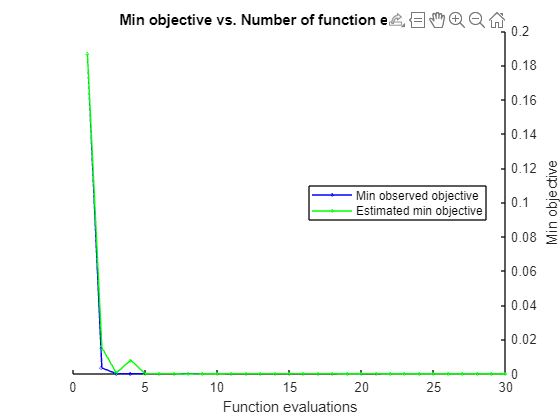


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 182.6124 seconds
Total objective function evaluation time: 174.0796

Best observed feasible point:
     Coding     BoxConstraint    KernelScale
    ________    _____________    ___________

    onevsone       44.954          0.20964  

Observed objective function value = 0
Estimated objective function value = -3.0343e-05
Function evaluation time = 0.23812

Best estimated feasible point (according to models):
     Coding     BoxConstraint    KernelScale
    ________    _____________    ___________

    onevsone       9.9221          2.2619   

Estimated objective function value = -5.1265e-05
Estimated function evalu


%% Split the data into 60% train, 20% validate, 20% test
[trainId,valId,testId] = dividerand(n_samples,.6,.2,.2);
Xtrain = X(trainId,:);
ytrain = y(trainId,:);
Xval = X(valId,:);
yval = y(valId,:);
Xtest = X(testId,:);
ytest = y(testId,:);

% Create the grid search object
grid_search = fitcecoc(Xtrain, ytrain,'OptimizeHyperparameters','auto',...
    'HyperparameterOptimizationOptions',...
    struct('AcquisitionFunctionName','expected-improvement-plus'));


% Fit the grid search to the data
grid_search.fit(Xtrain, ytrain);

% Evaluate the model on the validation set
val_accuracy = grid_search.predict(Xval);
val_accuracy = sum(val_accuracy == yval) / numel(yval);
fprintf('Validation set accuracy: %.2f%%\n', val_accuracy * 100);

Validation set accuracy: 100.00%



% Evaluate the model on the test set
test_accuracy = grid_search.predict(Xtest);
test_accuracy = sum(test_accuracy == ytest) / numel(ytest);
fprintf('Test set accuracy: %.2f%%\n', test_accuracy * 100);

Test set accuracy: 100.00%


Grid search can be computationally expensive, particularly when searching over many hyperparameters or a large range of values for each hyperparameter.